# Example Mission Segment

## Initialize Orbits

AU = 149597898; % [km]
mu_sun = 132712440017.99; % [km3 / s2]


ans = 5.8132

mu_kuat = 1.2748e6;
mu_vulcan = 2.8303e7;
mu_endor = 1.3957e6;
mu_tatooine = 3.2e5;

a_kuat = 0.6 * AU; % [km]
e_kuat = 0;
thetastar_kuat = linspace(0, deg2rad(360), 100);
w_kuat = deg2rad(40);

a_endor = 3.9 * AU; % [km]
e_endor = 0;
thetastar_endor = linspace(0, deg2rad(360), 300);
w_endor = deg2rad(90);

a_vulcan = 2.1 * AU; % [km]
e_vulcan = 0;
thetastar_vulcan = linspace(0, deg2rad(360), 300);
w_vulcan = deg2rad(90);

% Create transfer from Kuat to Endor
r_p_KE = 0.3 * AU;
r_a_KE = 4.2 * AU;

[a_KE, e_KE, p_KE, thetastar_KE, w_KE] = transfer_from_r_a_and_r_p(r_a_KE, r_p_KE, a_kuat, a_endor, w_kuat)

a_KE = 3.3660e+08

e_KE = 0.8667

p_KE = 8.3775e+07

thetastar_KE =     1.6478    1.6613    1.6749    1.6884    1.7019    1.7155    1.7290    1.7425    1.7561    1.7696    1.7831    1.7967    1.8102    1.8237    1.8373    1.8508    1.8643    1.8779    1.8914    1.9049    1.9185    1.9320    1.9455    1.9591    1.9726    1.9861    1.9997    2.0132    2.0267    2.0403    2.0538    2.0673    2.0809    2.0944    2.1079    2.1215    2.1350    2.1485    2.1621    2.1756    2.1891    2.2027    2.2162    2.2297    2.2433    2.2568    2.2703    2.2839    2.2974    2.3109


w_KE = -0.9497

% Calculate velocity relative to Endor at end of transfer
[v_inf_KE, gamma_f_KE] = relative_velocity(a_endor, mu_sun, p_KE, a_KE)

v_inf_KE = 10.7581

gamma_f_KE = 0.7469

## Patched Conic Arrival at Endor

% Compute arrival hyperbola
r_p_1 = 10000; % [km]

[e_arr, a_arr, v_p_arr, eta_arr] = patched_conic_hyperbola_parameters(r_p_1, mu_endor, v_inf_KE)

e_arr = 1.8292

a_arr = 1.2059e+04

v_p_arr = 12.7829

eta_arr = 123.1393

% Calculate delta V to get onto parking orbit from arrival hyperbola
v_p_1 = sqrt(mu_endor / r_p_1);

dV_arr = v_p_1 - v_p_arr

dV_arr = -0.9690

## Patched Conic Departure from Endor

% Define transfer ellipse from Endor to Vulcan
r_p_EV = 1.6 * AU;
r_a_EV = 4 * AU;

[a_EV, e_EV, p_EV, thetastar_EV, w_EV] = transfer_from_r_a_and_r_p(r_a_EV, r_p_EV, a_endor, a_vulcan, w_KE + thetastar_KE(end))

a_EV = 4.1887e+08

e_EV = 0.4286

p_EV = 3.4194e+08

thetastar_EV =    -2.8794   -2.8640   -2.8487   -2.8334   -2.8181   -2.8028   -2.7875   -2.7721   -2.7568   -2.7415   -2.7262   -2.7109   -2.6955   -2.6802   -2.6649   -2.6496   -2.6343   -2.6190   -2.6036   -2.5883   -2.5730   -2.5577   -2.5424   -2.5271   -2.5117   -2.4964   -2.4811   -2.4658   -2.4505   -2.4352   -2.4198   -2.4045   -2.3892   -2.3739   -2.3586   -2.3433   -2.3279   -2.3126   -2.2973   -2.2820   -2.2667   -2.2513   -2.2360   -2.2207   -2.2054   -2.1901   -2.1748   -2.1594   -2.1441   -2.1288


w_EV = 4.9173


% Calculate velocity relative to Endor at start of transfer
[v_inf_EV, gamma_0_EV] = relative_velocity(a_endor, mu_sun, p_EV, a_EV)

v_inf_EV = 4.1585

gamma_0_EV = 0.1873


% Compute departure hyperbola
r_p_2 = 8000; % [km]

[e_dep, a_dep, v_p_dep, eta_dep] = patched_conic_hyperbola_parameters(r_p_2, mu_endor, v_inf_EV)

e_dep = 1.0991

a_dep = 8.0708e+04

v_p_dep = 18.2108

eta_dep = 155.4800


% Calculate delta V to get onto parking orbit from arrival hyperbola
v_p_2 = sqrt(mu_endor / r_p_2);

dV_dep = v_p_dep - v_p_2

dV_dep = 5.0023

## Plot Heliocentric View

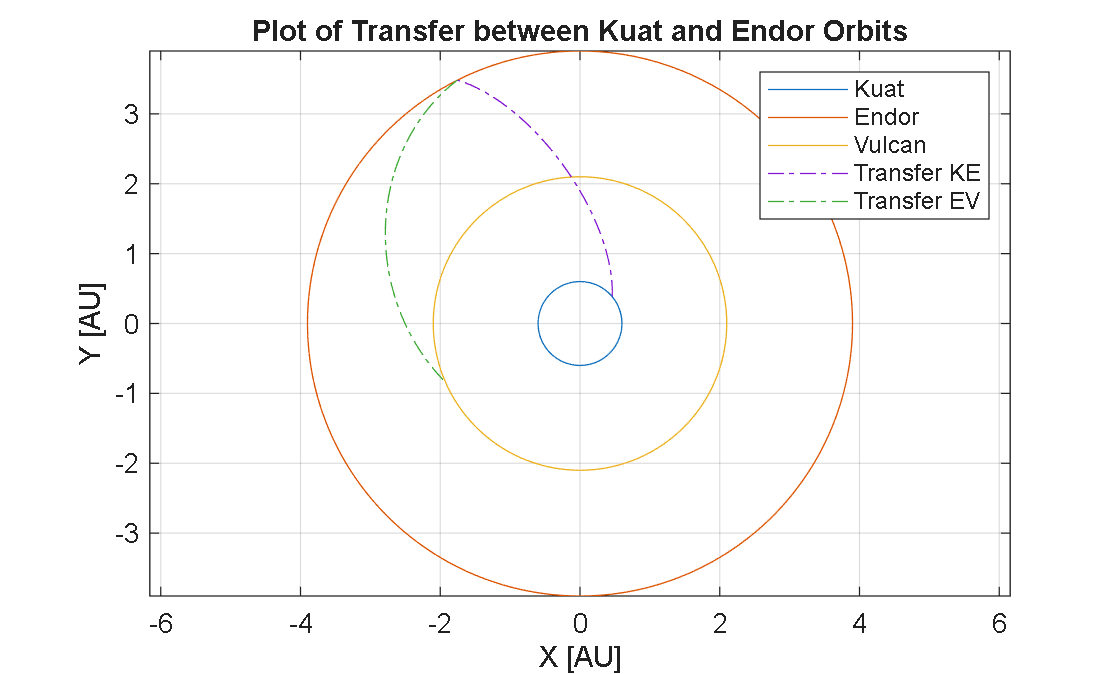

% Plot Kuat
orbitplot2D(a_kuat, e_kuat, thetastar_kuat, w_kuat, "Kuat", r_scale = AU); hold on
% Plot Endor
orbitplot2D(a_endor, e_endor, thetastar_endor, w_endor, "Endor", r_scale = AU)
% Plot Vulcan
orbitplot2D(a_vulcan, e_vulcan, thetastar_vulcan, w_vulcan, "Vulcan", r_scale = AU)
% Plot transfer from Kuat to Endor
orbitplot2D(a_KE, e_KE, thetastar_KE, w_KE, "Transfer KE", r_scale = AU, LineStyle = "-.", origin = [0; 0])
% Plot transfer from Endor to Vulcan
orbitplot2D(a_EV, e_EV, thetastar_EV, w_EV, "Transfer EV", r_scale = AU, LineStyle = "-.", origin = [0; 0])

axis equal
hold off
grid on
axis equal
title("Plot of Transfer between Kuat and Endor Orbits")
xlabel("X [AU]")
ylabel("Y [AU]")
legend()

## Plot Endor-centric View

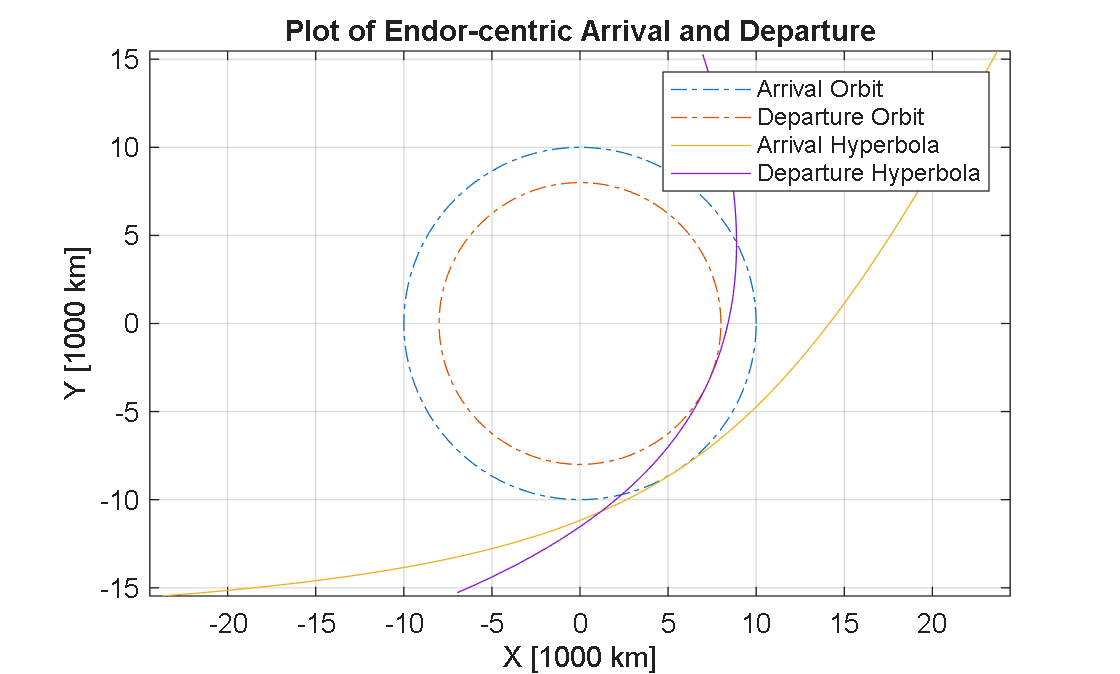

orbitplot2D(r_p_1, 0, linspace(0, 2 * pi, 100), 0, "Arrival Orbit", r_scale = 1000, LineStyle = "-.", origin = [0; 0]); hold on
orbitplot2D(r_p_2, 0, linspace(0, 2 * pi, 100), 0, "Departure Orbit", r_scale = 1000, LineStyle = "-.", origin = [0; 0])
orbitplot2D(a_arr, e_arr, linspace(-pi / 2, pi / 2, 100), deg2rad(eta_arr), "Arrival Hyperbola", r_scale = 1000, LineStyle = "-", origin = [0; 0]); hold on
orbitplot2D(a_dep, e_dep, linspace(-pi / 2, pi / 2, 100), deg2rad(eta_dep), "Departure Hyperbola", r_scale = 1000, LineStyle = "-", origin = [0; 0]); hold on


axis equal
hold off
grid on
axis equal
title("Plot of Endor-centric Arrival and Departure")
xlabel("X [1000 km]")
ylabel("Y [1000 km]")
legend()

## Helper Functions

function [v] = vis_viva(mu, a, r)
    v = sqrt(mu * (2 / r - 1 /a));
end

function [a_trans, e_trans, p_trans, thetastar_trans, w_trans] = transfer_from_r_a_and_r_p(r_a_trans, r_p_trans, a_A, a_B, w_A)
    a_trans = (r_p_trans + r_a_trans) / 2;
    e_trans = r_a_trans / a_trans - 1;
    p_trans = a_trans * (1 - e_trans ^ 2);
    % Rearrange orbit equation to get true anomaly when transfer orbit is at A
    thetastar_trans_0 = acos(1 / e_trans * (p_trans / a_A - 1));
    % Rearrange orbit equation to get true anomaly when transfer orbit is at B
    thetastar_trans_f = acos(1 / e_trans * (p_trans / a_B - 1));
    % Create true anomaly array for transfer orbit
    if thetastar_trans_f < thetastar_trans_0
        thetastar_trans_0 = -thetastar_trans_0;
        thetastar_trans_f = -thetastar_trans_f;
    end
    thetastar_trans = linspace(thetastar_trans_0, thetastar_trans_f, 100);
    w_trans = w_A - thetastar_trans_0;
end

function [v_inf, gamma_trans] = relative_velocity(r, mu, p, a)
    v_planet = sqrt(mu / r);
    v_trans = vis_viva(mu, a, r);
    h_trans = sqrt(mu * p);
    gamma_trans = acos(h_trans / (r * v_trans));
    % Law of cosines
    v_inf = sqrt(v_trans ^ 2 + v_planet ^ 2 - 2 * v_trans * v_planet * cos(gamma_trans));
end

function [e, a, v_p, eta] = patched_conic_hyperbola_parameters(r_p, mu, v_inf)
    e = 1 + r_p * v_inf ^ 2 / mu;
    a = mu / v_inf ^ 2;
    v_p = vis_viva(mu, a, r_p);
    eta = acosd(-1 / e);
end